# Representación Punto Flotante

## Punto Flotante

### Cambio de base

- Solo trabaja con enteros

decimal = 625;
binario = dec2bin(decimal)

binario = '1001110001'

% decimal a base 4
dec2base(732,4)

ans = '23130'

% hexadecimal a decimal
hex2dec('1FA')

ans = 506

### Formatos IEEE 754

- Un número en precisión simple

x=625

x = 625

class(x)

ans = 'double'

x0=single(x)

x0 = single
625

x1=typecast(x0,'uint32')

x1 = uint32
1142702080

b=dec2bin(x1,32)

b = '01000100000111000100000000000000'

length(b)

ans = 32

- Un número en precisión doble

x=-625

x = -625

class(x)

ans = 'double'

x0=double(x)

x0 = -625

x1=typecast(x0,'uint64')

x1 = uint64
13872080810812637184

b=dec2bin(x1,64)

b = '1100000010000011100010000000000000000000000000000000000000000000'

length(b)

ans = 64

### Trabajando con números con cifras decimales

x_bin = '10100010'

x_bin = '10100010'

y_bin = '0.10100000'

y_bin = '0.10100000'

bin2dec(x_bin)

ans = 162

%bin2dec(y_bin)
x_num = 2^7+2^5+2^1

x_num = 162

y_num = 2^(-1) + 2^(-3)

y_num = 0.6250

Usando notación científica


$$0.10100000_2 = 10100000 \times 2^{-8}$$


y_num = (2^7 + 2^5) / 2^8

y_num = 0.6250

Un número decimal en precisión simple

x=-3.625;
class(x)

ans = 'double'

x0=single(x)

x0 = single
-3.6250

x1=typecast(x0,'uint32')

x1 = uint32
3228041216

b=dec2bin(x1,32)

b = '11000000011010000000000000000000'

length(b)

ans = 32

s_str = b(1)

s_str = '1'

ei_str = b(2:9)

ei_str = '10000000'

m_str = b(10:end)

m_str = '11010000000000000000000'

s = str2double(s_str)

s = 1

BIAS=2^(8-1)-1;
E = bin2dec(ei_str)-BIAS

E = 1

x_sc = 1 + bin2dec(m_str) / 2^23

x_sc = 1.8125

x_num = (-1)^s * x_sc * 2^E

x_num = -3.6250

## Importancia de la representación punto flotante

Más alla de entender cómo funciona la computadora (ver la aritmética de punto flotante) podemos acotar la utilidad para 

- Optimizar el almacenamiento de datos

- La utilidad de los algoritmos y métodos numéricos

Caso: Datos de temperatura satelital

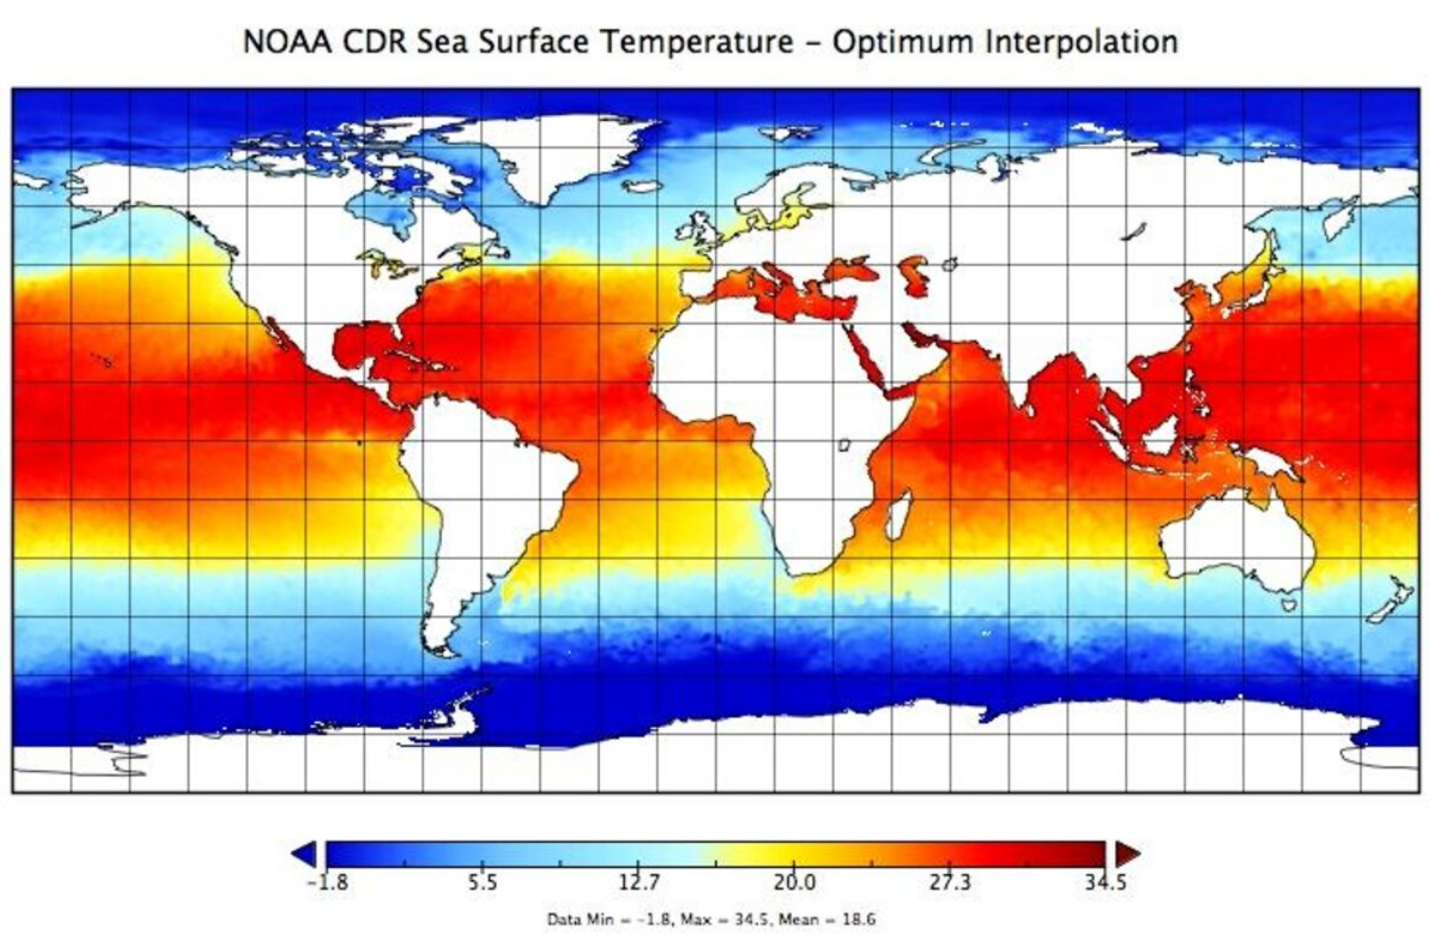

1. Descripción del producto: 

- OISST: Temperatura superficial del mar de interpolación óptima versión 2.1 ([https://www.ncei.noaa.gov/products/optimum-interpolation-sst](https://www.ncei.noaa.gov/products/optimum-interpolation-sst))

- Formato de almacenamiento: archivo netcdf ([https://es.wikipedia.org/wiki/NetCDF](https://es.wikipedia.org/wiki/NetCDF)) 

2. Obtención de datos: 

- Repositorio para descarga: [https://www.ncei.noaa.gov/data/sea-surface-temperature-optimum-interpolation/](https://www.ncei.noaa.gov/data/sea-surface-temperature-optimum-interpolation/) 

- Acceso libre y gratuito

3. Lectura de datos:

- Un archivo de datos netcdf almacena los datos con un formato específico: precisión simple, entero, etc

- Toda esa información viene en la metada del archivo

filename='oisst-avhrr-v02r01.20240905_preliminary.nc'

filename = 'oisst-avhrr-v02r01.20240905_preliminary.nc'

nc = load_netcdf(filename)

nc = struct with fields:
    time: 17049
    zlev: 0
     lat: [720×1 single]
     lon: [1440×1 single]
     sst: [1440×720 int16]
    anom: [1440×720 int16]
     err: [1440×720 int16]
     ice: [1440×720 int16]


4. Mapa de temperatura

- Seleccionar paleta

- Recortar zona

[lat,lon]=meshgrid(nc.lat,nc.lon-360);
sst=nc.sst;
[min(sst(:)) mean(sst(:)) max(sst(:))]

ans = 1×3 int16 row vector
    -999     629    3537


class(sst)

ans = 'int16'

sst=single(nc.sst);
[min(sst(:)) mean(sst(:)) max(sst(:))]

ans = 1×3 single row vector
1.0e+03 *

   -0.9990    0.6294    3.5370


sst(find(sst < -900))=NaN; % -999 es el valor perdido
sst=sst.*0.01;
[min(sst(:)) mean(sst(:)) max(sst(:))]

ans = 1×3 single row vector
   -1.8000       NaN   35.3700


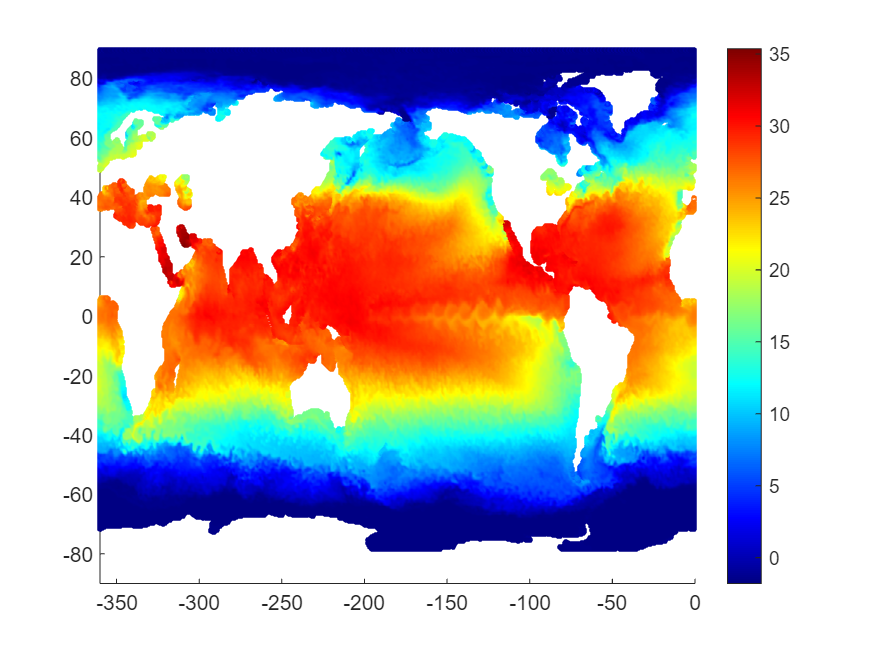

scatter(lon(:),lat(:),5,sst(:))
colormap("jet")
colorbar
xlim([-360 0])
ylim([-90 90])
print(gcf,'-dpng',[filename '.png'])

Funciones de usuario

function [ncstruct] = load_netcdf(filename)
% [ncstruct] = LOAD_NETCDF(filename) carga las variables de un netcdf en una estructura
% 
% Entrada:
% - filename: cadena con el nombre de un archivo netcdf
%
% Salida:
% - ncstruct: estructura con campos correspondientes a las variables del netcdf
% 
% Ejemplo:
% >> filename='./data/AVHRR/SST/2024/avhrr-only-v2.20240314.nc';
% >> [ncstruct] = load_netcdf(filename);

ncstruct = [] ;

ncid = netcdf.open(filename, 'write');
[ndims,nvars,ngatts,unlimdimid] = netcdf.inq(ncid);
for i=1:nvars
  tps=netcdf.inqVar(ncid,i-1);
  datps=netcdf.getVar(ncid,i-1);
  eval([,tps,'=datps;'])
  eval(['ncstruct.',tps,' = datps; '])
end
netcdf.close(ncid);
end